# The Effect of Speech Enhancement on Whisper Speech Recognition

ELEC5305 Audio Processing individual project

This Live Script is the single MATLAB demonstration file. It contains: 1. a quick classical-enhancement demonstration; 2. saved formal-result summaries; 3. optional switches for the complete MATLAB experiment; and 4. all MATLAB functions used by the project.

The Python steps (DeepFilterNet3, Whisper, WER and log-Mel analysis) are kept in the Colab notebook and Python scripts.

clear;
clc;
close all;

## 1. Settings

runQuickDemo = true;
showSavedFormalResults = true;

runPilotMetricCheck = false;
runDataPreparation = false;
runDevelopmentExperiment = false;
runTestExperiment = false;
runModifiedSpectralTest = false;
runFormalMetricCheck = false;

selectedAlpha = 1.50;
corpusRoot = "";  % Set this only when rebuilding the LibriSpeech split.

% Live Scripts can return an empty value from mfilename.  Read the path of
% the file open in the MATLAB Editor first, then use ordinary script paths.
scriptFolder = "";
try
    activeFile = string(matlab.desktop.editor.getActiveFilename);
    if strlength(activeFile) > 0
        scriptFolder = string(fileparts(activeFile));
    end
catch
    % The Editor is not available in some non-interactive MATLAB sessions.
end
if strlength(scriptFolder) == 0
    scriptFolder = string(fileparts(mfilename("fullpath")));
end
if strlength(scriptFolder) == 0
    scriptFolder = string(pwd);
end

formalRoot = locateFormalRoot(scriptFolder);
pilotRoot = locatePilotRoot(scriptFolder);

fprintf("Formal project root: %s\n", formalRoot);

Formal project root: D:\download\5305\ELEC5305_Submission_Package\Repository_Ready


fprintf("Pilot project root:  %s\n", pilotRoot);

Pilot project root:  D:\download\5305\ELEC5305_Pilot


## 2. Quick classical-enhancement demonstration

Quick demo source: full ELEC5305_Pilot folder.


          Condition           OutputSNRdB     STOI  
    ______________________    ___________    _______

    "No enhancement"           -7.89e-09     0.96421
    "Spectral subtraction"        2.4263     0.96642
    "Wiener filtering"            3.8392     0.96674



Spectral reconstruction error: 1.85e-16


Wiener reconstruction error:   1.85e-16


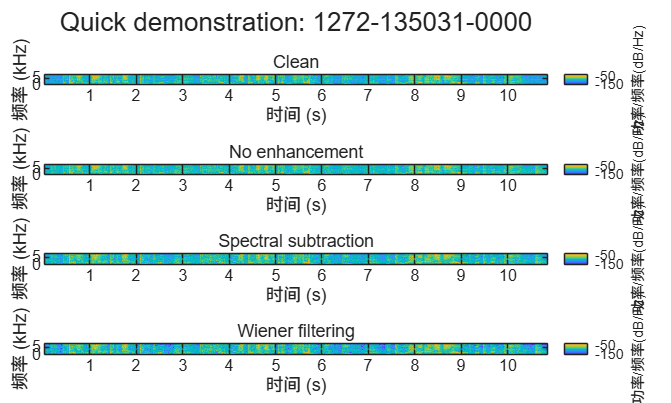

if runQuickDemo
    if strlength(pilotRoot) > 0
        % Use the original saved noise prefix when the full pilot folder exists.
        pilotManifest = readtable(fullfile(pilotRoot, "utterances.csv"), ...
            Delimiter=",", TextType="string", VariableNamingRule="preserve");
        demoId = string(pilotManifest{1, 1});
        cleanPath = fullfile(pilotRoot, "results", "audio", demoId + "_clean.wav");
        noisyPath = fullfile(pilotRoot, "results", "audio", demoId + "_noisy.wav");
        prefixPath = fullfile(pilotRoot, "results", "processing", ...
            demoId + "_noisy_with_prefix.wav");

        [cleanAudio, fs] = audioread(cleanPath);
        noisyAudio = audioread(noisyPath);
        noisyWithPrefix = audioread(prefixPath);
        fprintf("Quick demo source: full ELEC5305_Pilot folder.\n");
    else
        % Portable fallback: use the pilot WAV files included in the repository.
        pilotAudioRoot = fullfile(formalRoot, "results", "pilot", "audio");
        cleanFiles = dir(fullfile(pilotAudioRoot, "*_clean.wav"));
        assert(~isempty(cleanFiles), ...
            "Pilot audio was not found beside this Live Script.");
        [~, fileOrder] = sort({cleanFiles.name});
        cleanFile = string(cleanFiles(fileOrder(1)).name);
        demoId = erase(cleanFile, "_clean.wav");
        cleanPath = fullfile(pilotAudioRoot, cleanFile);
        noisyPath = fullfile(pilotAudioRoot, demoId + "_noisy.wav");

        [cleanAudio, fs] = audioread(cleanPath);
        noisyAudio = audioread(noisyPath);
        estimatedNoise = noisyAudio - cleanAudio;
        prefix = makeOneSecondPrefix(estimatedNoise, fs);
        noisyWithPrefix = [prefix; noisyAudio];
        fprintf("Quick demo source: packaged pilot audio fallback.\n");
    end

    [spectralAudio, spectralReconstructionError] = stft_enhance( ...
        double(noisyWithPrefix), fs, 512, 128, ...
        "spectral_subtraction", 1.0, 0.02);
    [wienerAudio, wienerReconstructionError] = stft_enhance( ...
        double(noisyWithPrefix), fs, 512, 128, ...
        "wiener", 1.0, 0.02);

    demoCondition = ["No enhancement"; "Spectral subtraction"; "Wiener filtering"];
    demoOutput = {noisyAudio; spectralAudio; wienerAudio};
    demoSNR = zeros(3, 1);
    demoSTOI = nan(3, 1);

    for i = 1:3
        demoSNR(i) = outputSNR(cleanAudio, demoOutput{i});
        if exist("stoi", "file") == 2
            demoSTOI(i) = stoi(demoOutput{i}, cleanAudio, fs);
        end
    end

    demoMetrics = table(demoCondition, demoSNR, demoSTOI, ...
        VariableNames=["Condition", "OutputSNRdB", "STOI"]);
    disp(demoMetrics);
    fprintf("Spectral reconstruction error: %.2e\n", spectralReconstructionError);
    fprintf("Wiener reconstruction error:   %.2e\n", wienerReconstructionError);

    figure(Name="One-utterance enhancement demonstration", Color="w");
    displaySignals = {cleanAudio, noisyAudio, spectralAudio, wienerAudio};
    displayTitles = ["Clean", "No enhancement", "Spectral subtraction", "Wiener filtering"];
    tiledlayout(4, 1, TileSpacing="compact", Padding="compact");
    for i = 1:4
        nexttile;
        spectrogram(displaySignals{i}, hann(512, "periodic"), 384, 512, fs, "yaxis");
        title(displayTitles(i));
        ylim([0 8]);
    end
    sgtitle("Quick demonstration: " + demoId);
end

## 3. Complete formal experiment results

Formal test: 50 utterances, 450 noisy mixtures, 1800 method conditions, plus 50 clean conditions.


Corpus-level WER uses total errors / total reference words.



                method                 wer_percent    substitutions    deletions    insertions    delta_wer_pp
    _______________________________    ___________    _____________    _________    __________    ____________

    "clean"                              5.0245             33             5             3               NaN  
    "noisy"                              10.526            598            59           116                 0  
    "spectral_subtraction"               10.253            590            55           108          -0.27233  
    "wiener"                             11.029            623            57           130           0.50381  
    "deepfilternet3"                     14.297            761            71           218            3.7718  
    "spectral_subtraction_modified"      10.621            620            49           111          0.095316  



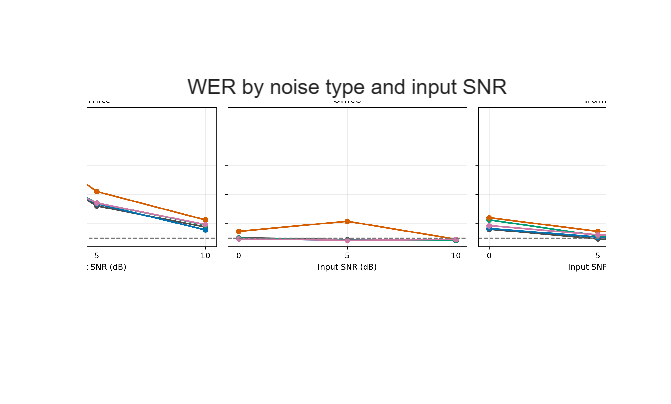

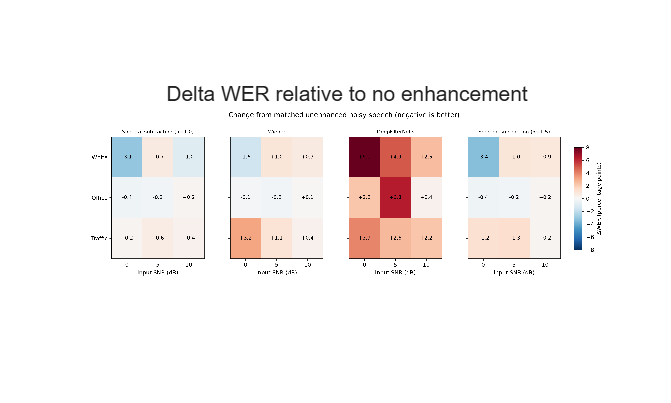

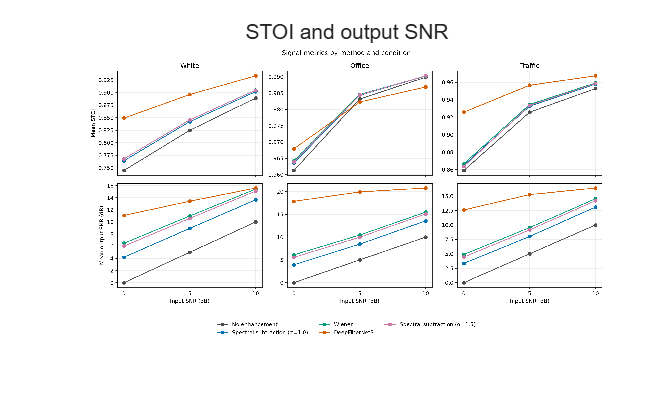

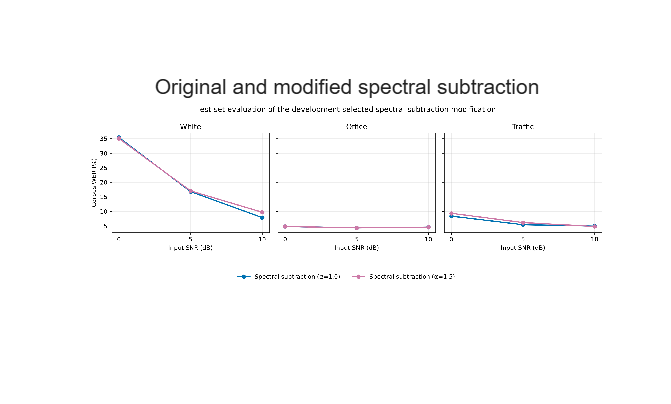

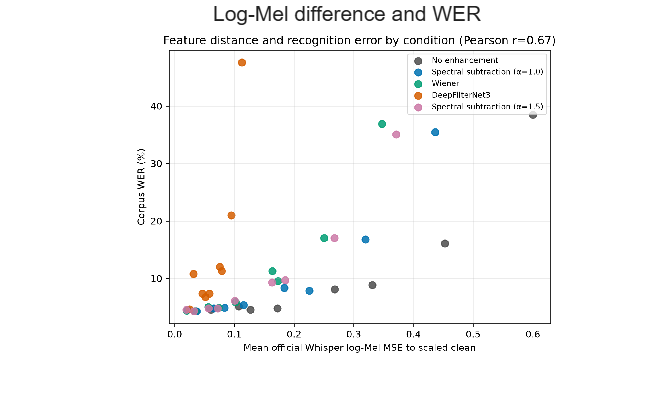

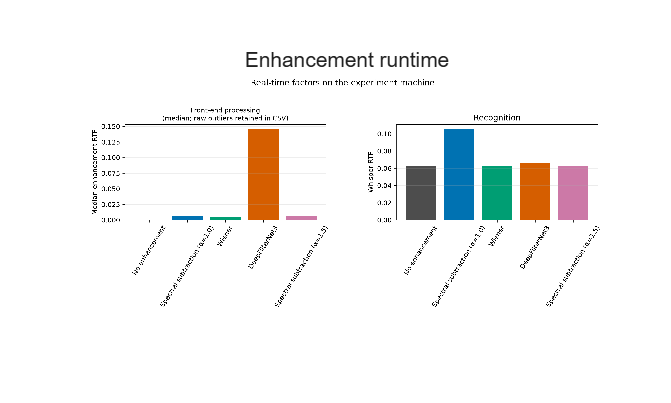

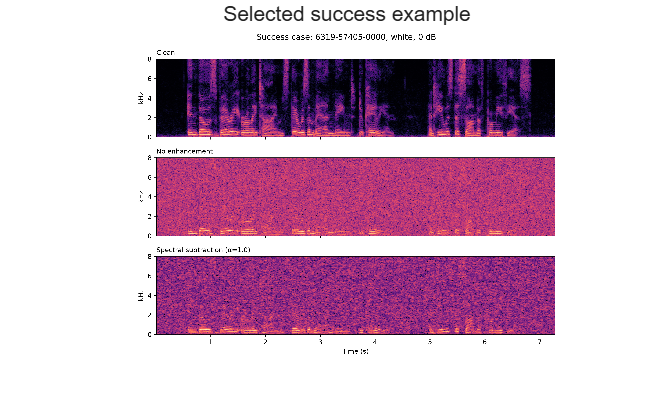

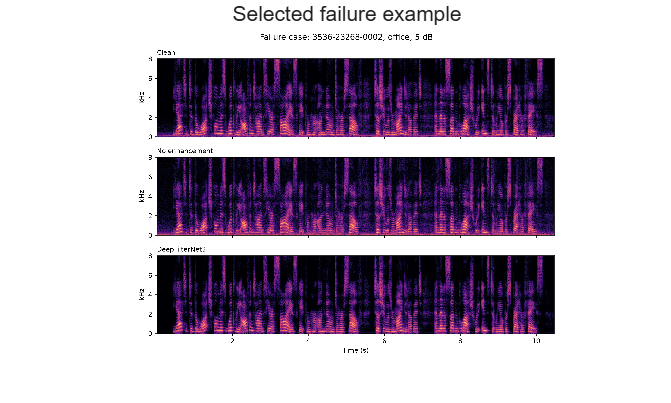


SUCCESS CASE: 6319-57405-0000, white noise, 0 dB, spectral_subtraction


Reference: IN THOSE VERY EARLY TIMES THERE WAS A MAN NAMED DEUCALION AND HE WAS THE SON OF PROMETHEUS


Noisy:     In those very early times, there was a man named because I think it was the sign up for me again.


Enhanced:  In those very early times, there was a man named Duque, and he was the son of Ponegia.


Error change: 9 to 2 (-38.9 WER points)



FAILURE CASE: 3536-23268-0002, office noise, 5 dB, deepfilternet3


Reference: YET DID THE WATCHFUL MISS WOODLEY OFTENTIMES HEAR A SIGH ESCAPE FROM HER UNKNOWN TO HERSELF TILL SHE WAS REMINDED OF IT AND THEN A SUDDEN BLUSH WOULD INSTANTLY OVERSPREAD HER FACE


Noisy:     Yet, did the watchful Miss Woodley oftentimes hear a sigh escape from her unknown to herself, till she was reminded of it, and then a sudden blush would instantly overspread her face?


Enhanced:  Yet did the watchful Miss Woodley oftentimes hear a sigh escape from her unknown to herself, till she was reminded of it, and then a sudden blush would instantly over-spread her face. Okay. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right. All right.


Error change: 0 to 51 (+159.4 WER points)



Failure-case sensitivity check:


            analysis                  method         errors    reference_words    wer_percent    delta_wer_pp
    _________________________    ________________    ______    _______________    ___________    ____________

    "all_rows"                   "deepfilternet3"     1050          7344            14.297          3.7718   
    "all_rows"                   "noisy"               773          7344            10.526               0   
    "matched_failure_removed"    "deepfilternet3"      999          7312            13.662          3.0908   
    "matched_failure_removed"    "noisy"               773          7312            10.572               0   



if showSavedFormalResults
    assert(strlength(formalRoot) > 0, "Repository_Ready was not found.");
    formalResultRoot = fullfile(formalRoot, "results", "formal", "test");
    overallPath = fullfile(formalResultRoot, "asr", "wer_summary_overall.csv");
    conditionPath = fullfile(formalResultRoot, "combined_condition_summary.csv");
    manifestPath = fullfile(formalResultRoot, "mixture_manifest.csv");

    overallWER = readtable(overallPath, TextType="string", ...
        VariableNamingRule="preserve");
    conditionSummary = readtable(conditionPath, TextType="string", ...
        VariableNamingRule="preserve");
    mixtureManifest = readtable(manifestPath, TextType="string", ...
        VariableNamingRule="preserve");

    cleanRow = conditionSummary(conditionSummary.noise_type == "clean", :);
    cleanSummary = table("clean", cleanRow.wer_percent(1), ...
        cleanRow.substitutions(1), cleanRow.deletions(1), ...
        cleanRow.insertions(1), NaN, ...
        VariableNames=["method", "wer_percent", "substitutions", ...
        "deletions", "insertions", "delta_wer_pp"]);
    finalWERSummary = [cleanSummary; overallWER(:, ["method", ...
        "wer_percent", "substitutions", "deletions", ...
        "insertions", "delta_wer_pp"])];

    utteranceCount = numel(unique(mixtureManifest.utteranceId));
    mixtureCount = height(mixtureManifest);
    fprintf("Formal test: %d utterances, %d noisy mixtures, " + ...
        "%d method conditions, plus %d clean conditions.\n", ...
        utteranceCount, mixtureCount, 4 * mixtureCount, utteranceCount);
    fprintf("Corpus-level WER uses total errors / total reference words.\n\n");
    disp(finalWERSummary);

    % The figures below were generated from the saved Python and MATLAB
    % result tables. Loading them here keeps the demonstration in one file.
    figureRoot = fullfile(formalResultRoot, "figures");
    resultFigureFiles = [
        "01_wer_vs_snr.png"
        "02_delta_wer_heatmap.png"
        "03_stoi_and_output_snr.png"
        "04_spectral_modification.png"
        "05_logmel_vs_wer.png"
        "06_runtime_rtf.png"
        "07_success_spectrogram.png"
        "07_failure_spectrogram.png"
        ];
    resultFigureNames = [
        "WER by noise type and input SNR"
        "Delta WER relative to no enhancement"
        "STOI and output SNR"
        "Original and modified spectral subtraction"
        "Log-Mel difference and WER"
        "Enhancement runtime"
        "Selected success example"
        "Selected failure example"
        ];

    for i = 1:numel(resultFigureFiles)
        figurePath = fullfile(figureRoot, resultFigureFiles(i));
        assert(isfile(figurePath), "A saved result figure was not found: %s", ...
            figurePath);
        figure(Name=resultFigureNames(i), Color="w");
        image(imread(figurePath));
        axis image off;
        title(resultFigureNames(i));
    end

    casePath = fullfile(formalResultRoot, "examples", "selected_cases.csv");
    sensitivityPath = fullfile(formalResultRoot, "examples", ...
        "failure_case_sensitivity.csv");
    selectedCases = readtable(casePath, Delimiter=",", TextType="string", ...
        VariableNamingRule="preserve");
    failureSensitivity = readtable(sensitivityPath, Delimiter=",", ...
        TextType="string", ...
        VariableNamingRule="preserve");

    for i = 1:height(selectedCases)
        fprintf("\n%s CASE: %s, %s noise, %.0f dB, %s\n", ...
            upper(selectedCases.case_type(i)), selectedCases.utterance_id(i), ...
            selectedCases.noise_type(i), selectedCases.target_snr_db(i), ...
            selectedCases.method(i));
        fprintf("Reference: %s\n", selectedCases.reference_text(i));
        fprintf("Noisy:     %s\n", selectedCases.noisy_hypothesis_text(i));
        fprintf("Enhanced:  %s\n", selectedCases.hypothesis_text(i));
        fprintf("Error change: %d to %d (%+.1f WER points)\n", ...
            selectedCases.noisy_errors(i), selectedCases.errors(i), ...
            selectedCases.delta_utterance_wer_pp(i));
    end

    fprintf("\nFailure-case sensitivity check:\n");
    disp(failureSensitivity);
end

## 4. Optional full MATLAB workflow

if runDataPreparation
    assert(strlength(corpusRoot) > 0 && isfolder(corpusRoot), ...
        "Set corpusRoot to the LibriSpeech dev-clean-2 folder.");
    [developmentSplit, testSplit] = prepare_data_splits(formalRoot, corpusRoot);
    disp(developmentSplit(:, ["utterance_id", "speaker_id", "duration_seconds"]));
    disp(testSplit(1:min(10, height(testSplit)), ...
        ["utterance_id", "speaker_id", "duration_seconds"]));
end

if runDevelopmentExperiment
    developmentMixtures = run_classical_experiment(formalRoot, "development", true);
    disp(developmentMixtures(1:min(10, height(developmentMixtures)), :));
end

if runTestExperiment
    testMixtures = run_classical_experiment(formalRoot, "test", false);
    disp(testMixtures(1:min(10, height(testMixtures)), :));
end

if runModifiedSpectralTest
    modifiedTiming = generate_modified_spectral_test(formalRoot, selectedAlpha);
    disp(modifiedTiming(1:min(10, height(modifiedTiming)), :));
end

if runFormalMetricCheck
    [formalPerFile, formalSummary] = evaluate_formal_metrics( ...
        formalRoot, "test", false, true);
    disp(formalSummary);
end

if runPilotMetricCheck
    [pilotPerFile, pilotSummary] = evaluate_pilot_metrics(pilotRoot);
    disp(pilotSummary);
end

## 5. MATLAB and Python division

MATLAB prepares audio, makes mixtures, runs the two classical methods and calculates SNR and STOI. Python runs DeepFilterNet3, Whisper, WER, log-Mel analysis and the final plots. No neural model is trained.

fprintf("\nMATLAB demonstration completed.\n");


MATLAB demonstration completed.


fprintf("Use the Colab notebook for DeepFilterNet3 and Whisper.\n");

Use the Colab notebook for DeepFilterNet3 and Whisper.


## Local functions

The remaining sections contain all MATLAB functions used by the project.

function [development, test] = prepare_data_splits(projectRoot, corpusRoot)
%PREPARE_DATA_SPLITS Create separate development and test sets.
% Both sets use LibriSpeech dev-clean-2. They are not the official test set.

arguments
    projectRoot (1,1) string
    corpusRoot (1,1) string
end

splitDir = fullfile(projectRoot, "data", "splits");
devManifestPath = fullfile(splitDir, "development_manifest.csv");
testManifestPath = fullfile(splitDir, "test_manifest.csv");
if isfile(devManifestPath) && isfile(testManifestPath)
    development = readtable(devManifestPath, Delimiter=",", ...
        TextType="string", VariableNamingRule="preserve");
    test = readtable(testManifestPath, Delimiter=",", ...
        TextType="string", VariableNamingRule="preserve");
    return;
end

if ~isfolder(splitDir), mkdir(splitDir); end
speechFiles = dir(fullfile(corpusRoot, "**", "*.flac"));
textFiles = dir(fullfile(corpusRoot, "**", "*.trans.txt"));
assert(~isempty(speechFiles) && ~isempty(textFiles), ...
    "LibriSpeech audio or transcript files were not found.");

transcriptMap = containers.Map(KeyType="char", ValueType="char");
for i = 1:numel(textFiles)
    lines = splitlines(string(fileread(fullfile(textFiles(i).folder, textFiles(i).name))));
    for j = 1:numel(lines)
        token = regexp(char(strtrim(lines(j))), '^(\S+)\s+(.+)$', 'tokens', 'once');
        if ~isempty(token)
            transcriptMap(token{1}) = token{2};
        end
    end
end

paths = sort(string(fullfile({speechFiles.folder}, {speechFiles.name}))');
utteranceId = strings(0, 1);
speakerId = strings(0, 1);
referenceText = strings(0, 1);
sourcePath = strings(0, 1);
durationSeconds = zeros(0, 1);

for i = 1:numel(paths)
    [~, id] = fileparts(paths(i));
    parts = split(string(id), "-");
    info = audioinfo(paths(i));
    if info.SampleRate ~= 16000 || info.NumChannels ~= 1 || ...
            info.Duration < 2 || info.Duration > 15 || ~isKey(transcriptMap, id)
        continue;
    end
    utteranceId(end+1, 1) = string(id); %#ok<AGROW>
    speakerId(end+1, 1) = parts(1); %#ok<AGROW>
    referenceText(end+1, 1) = string(transcriptMap(id)); %#ok<AGROW>
    sourcePath(end+1, 1) = paths(i); %#ok<AGROW>
    durationSeconds(end+1, 1) = info.Duration; %#ok<AGROW>
end

candidates = table(utteranceId, speakerId, referenceText, sourcePath, durationSeconds);
candidates = sortrows(candidates, ["speakerId", "utteranceId"]);
speakers = unique(candidates.speakerId, "stable");
assert(numel(speakers) >= 15, "Too few speakers for a disjoint split.");

devSpeakers = speakers(1:5);
devRows = zeros(5, 1);
for i = 1:5
    devRows(i) = find(candidates.speakerId == devSpeakers(i), 1, "first");
end

testSpeakers = speakers(6:end);
testRows = zeros(0, 1);
roundIndex = 1;
while numel(testRows) < 50
    added = false;
    for i = 1:numel(testSpeakers)
        speakerRows = find(candidates.speakerId == testSpeakers(i));
        if numel(speakerRows) >= roundIndex
            testRows(end+1, 1) = speakerRows(roundIndex); %#ok<AGROW>
            added = true;
            if numel(testRows) == 50, break; end
        end
    end
    assert(added, "Could not select 50 test utterances.");
    roundIndex = roundIndex + 1;
end

development = buildManifest(candidates(devRows, :), "development", projectRoot);
test = buildManifest(candidates(testRows, :), "test", projectRoot);
assert(isempty(intersect(development.speaker_id, test.speaker_id)), ...
    "Development and test speakers overlap.");

writetable(development, devManifestPath);
writetable(test, testManifestPath);
fprintf("Development: %d utterances, %d speakers\n", ...
    height(development), numel(unique(development.speaker_id)));
fprintf("Test: %d utterances, %d speakers\n", ...
    height(test), numel(unique(test.speaker_id)));
end


function manifest = buildManifest(rows, splitName, projectRoot)
cleanDir = fullfile(projectRoot, "data", "clean", splitName);
if ~isfolder(cleanDir), mkdir(cleanDir); end
relativePath = strings(height(rows), 1);
for i = 1:height(rows)
    outputPath = fullfile(cleanDir, rows.utteranceId(i) + ".wav");
    if ~isfile(outputPath)
        [audio, fs] = audioread(rows.sourcePath(i));
        assert(fs == 16000 && size(audio, 2) == 1);
        audiowrite(outputPath, audio, fs, BitsPerSample=24);
    end
    relativePath(i) = "data/clean/" + splitName + "/" + rows.utteranceId(i) + ".wav";
end
manifest = table(rows.utteranceId, relativePath, rows.referenceText, ...
    repmat(string(splitName), height(rows), 1), ...
    repmat("LibriSpeech dev-clean-2", height(rows), 1), ...
    rows.sourcePath, rows.speakerId, rows.durationSeconds, ...
    'VariableNames', {'utterance_id', 'clean_wav', 'reference_text', ...
    'project_split', 'source_partition', 'source_path', 'speaker_id', ...
    'duration_seconds'});
end

function mixtureManifest = run_classical_experiment(projectRoot, splitName, runAlphaSweep)
%RUN_CLASSICAL_EXPERIMENT Create mixtures and classical enhanced outputs.
% The same saved noisy-with-prefix signal is used by both classical methods.

arguments
    projectRoot (1,1) string
    splitName (1,1) string {mustBeMember(splitName,["development","test"])}
    runAlphaSweep (1,1) logical = false
end

fs = 16000;
prefixSamples = fs;
frameLength = 512;
hopLength = 128;
floorRatio = 0.02;
baselineAlpha = 1.0;
alphaCandidates = [0.75 1.00 1.25 1.50 2.00];
noiseNames = ["white", "office", "traffic"];
snrTargets = [0 5 10];

manifestPath = fullfile(projectRoot, "data", "splits", ...
    splitName + "_manifest.csv");
manifest = readtable(manifestPath, Delimiter=",", TextType="string", ...
    VariableNamingRule="preserve");
office = readNoise(fullfile(projectRoot, "data", "noise", "office.wav"), fs);
traffic = readNoise(fullfile(projectRoot, "data", "noise", "traffic.wav"), fs);

resultRoot = fullfile(projectRoot, "results", "formal", splitName);
audioRoot = fullfile(resultRoot, "audio");
processingRoot = fullfile(resultRoot, "processing");
if ~isfolder(audioRoot), mkdir(audioRoot); end
if ~isfolder(processingRoot), mkdir(processingRoot); end

nRows = height(manifest) * numel(noiseNames) * numel(snrTargets);
utteranceId = strings(nRows, 1); projectSplit = repmat(splitName, nRows, 1);
noiseType = strings(nRows, 1); targetSNRdB = zeros(nRows, 1);
measuredInputSNRdB = zeros(nRows, 1); randomSeed = zeros(nRows, 1);
noiseStartSample16k = nan(nRows, 1); noiseGain = zeros(nRows, 1);
commonScale = zeros(nRows, 1); prefixLengthSamples = repmat(prefixSamples, nRows, 1);
cleanRelativePath = strings(nRows, 1); noisyRelativePath = strings(nRows, 1);
prefixRelativePath = strings(nRows, 1); spectralRelativePath = strings(nRows, 1);
wienerRelativePath = strings(nRows, 1); reconstructionError = zeros(nRows, 1);
spectralSeconds = zeros(nRows, 1); wienerSeconds = zeros(nRows, 1);
durationSeconds = zeros(nRows, 1);

row = 0;
for u = 1:height(manifest)
    id = string(manifest.utterance_id(u));
    [clean, cleanFs] = audioread(fullfile(projectRoot, manifest.clean_wav(u)));
    assert(cleanFs == fs && size(clean, 2) == 1);
    clean = double(clean(:)) - mean(clean);
    speechLength = numel(clean);
    utteranceDir = fullfile(audioRoot, id);
    prefixDir = fullfile(processingRoot, id);
    if ~isfolder(utteranceDir), mkdir(utteranceDir); end
    if ~isfolder(prefixDir), mkdir(prefixDir); end
    cleanPath = fullfile(utteranceDir, "clean.wav");
    if ~isfile(cleanPath)
        audiowrite(cleanPath, clean, fs, BitsPerSample=24);
    end

    for n = 1:numel(noiseNames)
        for q = 1:numel(snrTargets)
            row = row + 1;
            seed = 5305 + u * 100 + n * 10 + q;
            rng(seed, "twister");
            totalLength = prefixSamples + speechLength;
            if noiseNames(n) == "white"
                baseNoise = randn(totalLength, 1);
                startSample = NaN;
            else
                sourceNoise = office;
                if noiseNames(n) == "traffic", sourceNoise = traffic; end
                startSample = randi(numel(sourceNoise) - totalLength + 1);
                baseNoise = sourceNoise(startSample:startSample + totalLength - 1);
            end
            baseNoise = baseNoise - mean(baseNoise);
            speechNoise = baseNoise(prefixSamples+1:end);
            gain = sqrt(mean(clean.^2) / ...
                (mean(speechNoise.^2) * 10^(snrTargets(q)/10) + eps));
            scaledNoise = baseNoise * gain;
            paddedClean = [zeros(prefixSamples, 1); clean];
            mixture = paddedClean + scaledNoise;
            scale = min(1, 0.95 / max(abs([paddedClean; mixture])));
            mixture = mixture * scale;
            scaledReference = clean * scale;
            noisy = mixture(prefixSamples+1:end);

            stem = noiseNames(n) + "_" + snrTargets(q) + "dB";
            noisyPath = fullfile(utteranceDir, stem + "_noisy.wav");
            prefixPath = fullfile(prefixDir, stem + "_noisy_with_prefix.wav");
            spectralPath = fullfile(utteranceDir, stem + "_spectral_subtraction.wav");
            wienerPath = fullfile(utteranceDir, stem + "_wiener.wav");
            if ~isfile(noisyPath), audiowrite(noisyPath, noisy, fs, BitsPerSample=24); end
            if ~isfile(prefixPath), audiowrite(prefixPath, mixture, fs, BitsPerSample=24); end

            storedNoisy = audioread(noisyPath);
            inputSNR = 10 * log10(sum(scaledReference.^2) / ...
                (sum((storedNoisy - scaledReference).^2) + eps));
            assert(abs(inputSNR - snrTargets(q)) < 0.01, ...
                "Stored input SNR is incorrect.");

            tic;
            [spectral, recError1] = stft_enhance(mixture, prefixSamples, ...
                frameLength, hopLength, "spectral_subtraction", ...
                baselineAlpha, floorRatio);
            spectralTime = toc;
            tic;
            [wiener, recError2] = stft_enhance(mixture, prefixSamples, ...
                frameLength, hopLength, "wiener", baselineAlpha, floorRatio);
            wienerTime = toc;
            assert(max(recError1, recError2) < 1e-9, "STFT reconstruction failed.");
            assert(all(isfinite([spectral; wiener])));
            assert(max(abs([spectral; wiener])) < 1);
            if ~isfile(spectralPath), audiowrite(spectralPath, spectral, fs, BitsPerSample=24); end
            if ~isfile(wienerPath), audiowrite(wienerPath, wiener, fs, BitsPerSample=24); end

            if runAlphaSweep
                for alpha = alphaCandidates
                    alphaName = replace(sprintf("%.2f", alpha), ".", "p");
                    alphaPath = fullfile(utteranceDir, ...
                        stem + "_spectral_alpha_" + alphaName + ".wav");
                    if ~isfile(alphaPath)
                        alphaAudio = stft_enhance(mixture, prefixSamples, ...
                            frameLength, hopLength, "spectral_subtraction", ...
                            alpha, floorRatio);
                        audiowrite(alphaPath, alphaAudio, fs, BitsPerSample=24);
                    end
                end
            end

            utteranceId(row) = id; noiseType(row) = noiseNames(n);
            targetSNRdB(row) = snrTargets(q); measuredInputSNRdB(row) = inputSNR;
            randomSeed(row) = seed; noiseStartSample16k(row) = startSample;
            noiseGain(row) = gain; commonScale(row) = scale;
            cleanRelativePath(row) = relative(projectRoot, cleanPath);
            noisyRelativePath(row) = relative(projectRoot, noisyPath);
            prefixRelativePath(row) = relative(projectRoot, prefixPath);
            spectralRelativePath(row) = relative(projectRoot, spectralPath);
            wienerRelativePath(row) = relative(projectRoot, wienerPath);
            reconstructionError(row) = max(recError1, recError2);
            spectralSeconds(row) = spectralTime; wienerSeconds(row) = wienerTime;
            durationSeconds(row) = speechLength / fs;
            fprintf("%s %s %d dB complete\n", id, noiseNames(n), snrTargets(q));
        end
    end
end

mixtureManifest = table(utteranceId, projectSplit, noiseType, targetSNRdB, ...
    measuredInputSNRdB, randomSeed, noiseStartSample16k, noiseGain, commonScale, ...
    prefixLengthSamples, durationSeconds, cleanRelativePath, noisyRelativePath, ...
    prefixRelativePath, spectralRelativePath, wienerRelativePath, ...
    reconstructionError, spectralSeconds, wienerSeconds);
writetable(mixtureManifest, fullfile(resultRoot, "mixture_manifest.csv"));

settings = struct(fs=fs, prefix_samples=prefixSamples, frame_length=frameLength, ...
    hop_length=hopLength, window="sqrt periodic Hann", floor_ratio=floorRatio, ...
    spectral_subtraction_alpha=baselineAlpha, alpha_candidates=alphaCandidates, ...
    snr_targets_db=snrTargets, random_seed_formula="5305 + 100*u + 10*n + q", ...
    clipping_peak_limit=0.95);
fid = fopen(fullfile(resultRoot, "classical_settings.json"), "w");
fprintf(fid, "%s", jsonencode(settings, PrettyPrint=true)); fclose(fid);
end


function noise = readNoise(path, expectedFs)
[noise, fs] = audioread(path);
assert(fs == expectedFs && size(noise, 2) == 1, ...
    "Noise must be mono 16 kHz audio: %s", path);
noise = double(noise(:));
end


function path = relative(root, absolutePath)
root = replace(string(root), "\", "/");
absolutePath = replace(string(absolutePath), "\", "/");
path = extractAfter(absolutePath, strlength(root) + 1);
if startsWith(path, "/"), path = extractAfter(path, 1); end
end

function [perFile, summary] = evaluate_formal_metrics(projectRoot, splitName, includeAlphaSweep, includeModified)
%EVALUATE_FORMAL_METRICS Compute aligned waveform SNR and STOI.

arguments
    projectRoot (1,1) string
    splitName (1,1) string {mustBeMember(splitName,["development","test"])}
    includeAlphaSweep (1,1) logical = false
    includeModified (1,1) logical = false
end

resultRoot = fullfile(projectRoot, "results", "formal", splitName);
mixtures = readtable(fullfile(resultRoot, "mixture_manifest.csv"), ...
    Delimiter=",", TextType="string", VariableNamingRule="preserve");
deepfilter = readtable(fullfile(resultRoot, "deepfilter_manifest.csv"), ...
    Delimiter=",", TextType="string", VariableNamingRule="preserve");
modified = table;
methods = ["noisy", "spectral_subtraction", "wiener", "deepfilternet3"];
alphas = [0.75 1.00 1.25 1.50 2.00];
if includeAlphaSweep
    for alpha = alphas
        methods(end+1) = "spectral_alpha_" + replace(sprintf("%.2f", alpha), ".", "p"); %#ok<AGROW>
    end
end
if includeModified
    modified = readtable(fullfile(resultRoot, "modified_spectral_manifest.csv"), ...
        Delimiter=",", TextType="string", VariableNamingRule="preserve");
    methods(end+1) = "spectral_subtraction_modified";
end

nRows = height(mixtures) * numel(methods);
utteranceId = strings(nRows, 1); noiseType = strings(nRows, 1);
targetSNRdB = zeros(nRows, 1); method = strings(nRows, 1);
outputSNRdB = zeros(nRows, 1); snrImprovementdB = zeros(nRows, 1);
stoiScore = zeros(nRows, 1); estimatedLagSamples = zeros(nRows, 1);
durationSeconds = zeros(nRows, 1); processingSeconds = nan(nRows, 1);
realTimeFactor = nan(nRows, 1); peakAmplitude = zeros(nRows, 1);
audioRelativePath = strings(nRows, 1);

pool = gcp("nocreate");
if isempty(pool)
    parpool("Processes", min(8, feature("numcores")));
end
nMethods = numel(methods);
parfor rowIndex = 1:nRows
    i = ceil(rowIndex / nMethods);
    m = mod(rowIndex - 1, nMethods) + 1;
    id = mixtures.utteranceId(i);
    [baseClean, fs] = audioread(fullfile(projectRoot, mixtures.cleanRelativePath(i)));
    assert(fs == 16000 && size(baseClean, 2) == 1);
    reference = double(baseClean(:)) * mixtures.commonScale(i);
    duration = numel(reference) / fs;
    deepUse = deepfilter.utterance_id == id & ...
        deepfilter.noise_type == mixtures.noiseType(i) & ...
        deepfilter.target_snr_db == mixtures.targetSNRdB(i);
    assert(nnz(deepUse) == 1, "Missing DeepFilterNet timing row.");

        currentMethod = methods(m);
        if currentMethod == "noisy"
            relativePath = mixtures.noisyRelativePath(i); elapsed = 0;
        elseif currentMethod == "spectral_subtraction"
            relativePath = mixtures.spectralRelativePath(i); elapsed = mixtures.spectralSeconds(i);
        elseif currentMethod == "wiener"
            relativePath = mixtures.wienerRelativePath(i); elapsed = mixtures.wienerSeconds(i);
        elseif currentMethod == "deepfilternet3"
            relativePath = deepfilter.deepfilter_relative_path(deepUse);
            elapsed = deepfilter.processing_seconds(deepUse);
        elseif currentMethod == "spectral_subtraction_modified"
            modifiedUse = modified.utterance_id == id & ...
                modified.noise_type == mixtures.noiseType(i) & ...
                modified.target_snr_db == mixtures.targetSNRdB(i);
            assert(nnz(modifiedUse) == 1, "Missing modified spectral timing row.");
            relativePath = modified.output_relative_path(modifiedUse);
            elapsed = modified.processing_seconds(modifiedUse);
        else
            token = extractAfter(currentMethod, "spectral_alpha_");
            stem = mixtures.noiseType(i) + "_" + mixtures.targetSNRdB(i) + "dB";
            relativePath = fullfile("results", "formal", splitName, "audio", id, ...
                stem + "_spectral_alpha_" + token + ".wav");
            relativePath = replace(relativePath, "\", "/"); elapsed = NaN;
        end
        [processed, processedFs] = audioread(fullfile(projectRoot, relativePath));
        processed = double(processed(:));
        assert(processedFs == fs && numel(processed) == numel(reference));
        assert(all(isfinite(processed)));
        lag = finddelay(reference, processed, round(0.01 * fs));
        currentSNR = 10 * log10(sum(reference.^2) / ...
            (sum((reference - processed).^2) + eps));

        utteranceId(rowIndex) = id; noiseType(rowIndex) = mixtures.noiseType(i);
        targetSNRdB(rowIndex) = mixtures.targetSNRdB(i); method(rowIndex) = currentMethod;
        outputSNRdB(rowIndex) = currentSNR;
        snrImprovementdB(rowIndex) = currentSNR - mixtures.measuredInputSNRdB(i);
        stoiScore(rowIndex) = stoi(processed, reference, fs);
        estimatedLagSamples(rowIndex) = lag; durationSeconds(rowIndex) = duration;
        processingSeconds(rowIndex) = elapsed; realTimeFactor(rowIndex) = elapsed / duration;
        peakAmplitude(rowIndex) = max(abs(processed)); audioRelativePath(rowIndex) = relativePath;
end

perFile = table(utteranceId, noiseType, targetSNRdB, method, outputSNRdB, ...
    snrImprovementdB, stoiScore, estimatedLagSamples, durationSeconds, ...
    processingSeconds, realTimeFactor, peakAmplitude, audioRelativePath);
writetable(perFile, fullfile(resultRoot, "metrics_per_file.csv"));

[groups, noise, snr, groupMethod] = findgroups(perFile.noiseType, ...
    perFile.targetSNRdB, perFile.method);
summary = table(noise, snr, groupMethod, splitapply(@numel, perFile.outputSNRdB, groups), ...
    splitapply(@mean, perFile.outputSNRdB, groups), ...
    splitapply(@mean, perFile.snrImprovementdB, groups), ...
    splitapply(@mean, perFile.stoiScore, groups), ...
    splitapply(@(x) max(abs(x)), perFile.estimatedLagSamples, groups), ...
    splitapply(@(x) mean(x, "omitnan"), perFile.realTimeFactor, groups), ...
    'VariableNames', {'noise_type', 'target_snr_db', 'method', 'n_files', ...
    'mean_output_snr_db', 'mean_snr_improvement_db', 'mean_stoi', ...
    'max_abs_lag_samples', 'mean_real_time_factor'});
writetable(summary, fullfile(resultRoot, "metrics_summary.csv"));
disp(summary);
end

function [perUtterance, summary] = evaluate_pilot_metrics(projectRoot)
%EVALUATE_PILOT_METRICS Evaluate the five completed pilot conditions.
% Use only the aligned speech part. Do not score the noise-only prefix.

arguments
    projectRoot (1,1) string
end

fsExpected = 16000;
conditions = ["clean", "noisy", "spectral_subtraction", ...
    "wiener", "deepfilter"];
manifest = readtable(fullfile(projectRoot, "utterances.csv"), ...
    Delimiter=",", ReadVariableNames=true, TextType="string", ...
    VariableNamingRule="preserve");
audioDir = fullfile(projectRoot, "results", "audio");
analysisDir = fullfile(projectRoot, "results", "analysis");
if ~isfolder(analysisDir)
    mkdir(analysisDir);
end

nRows = height(manifest) * numel(conditions);
utteranceId = strings(nRows, 1);
condition = strings(nRows, 1);
sampleRate = zeros(nRows, 1);
referenceSamples = zeros(nRows, 1);
processedSamples = zeros(nRows, 1);
estimatedLagSamples = zeros(nRows, 1);
outputSNRdB = nan(nRows, 1);
snrImprovementdB = nan(nRows, 1);
stoiScore = nan(nRows, 1);
peakAmplitude = nan(nRows, 1);

rowIndex = 0;
for u = 1:height(manifest)
    % Use the first column by position because the CSV may include a UTF-8 BOM.
    id = string(manifest{u, 1});
    cleanPath = fullfile(audioDir, id + "_clean.wav");
    [clean, fs] = audioread(cleanPath);
    assert(fs == fsExpected && size(clean, 2) == 1, ...
        "Clean reference must be mono 16 kHz audio.");
    clean = double(clean(:));

    noisyPath = fullfile(audioDir, id + "_noisy.wav");
    noisy = audioread(noisyPath);
    assert(numel(noisy) == numel(clean), "Noisy audio length mismatch.");
    inputSNR = 10 * log10(sum(clean.^2) / ...
        (sum((double(noisy(:)) - clean).^2) + eps));

    for c = 1:numel(conditions)
        rowIndex = rowIndex + 1;
        currentCondition = conditions(c);
        audioPath = fullfile(audioDir, id + "_" + currentCondition + ".wav");
        [processed, processedFs] = audioread(audioPath);
        processed = double(processed(:));

        assert(processedFs == fsExpected, "Unexpected sample rate: %s", audioPath);
        assert(numel(processed) == numel(clean), "Length mismatch: %s", audioPath);
        assert(all(isfinite(processed)), "Non-finite samples: %s", audioPath);

        lag = finddelay(clean, processed, round(0.05 * fsExpected));
        errorSignal = clean - processed;
        if currentCondition == "clean"
            currentSNR = Inf;
            currentImprovement = NaN;
        else
            currentSNR = 10 * log10(sum(clean.^2) / ...
                (sum(errorSignal.^2) + eps));
            currentImprovement = currentSNR - inputSNR;
        end

        utteranceId(rowIndex) = id;
        condition(rowIndex) = currentCondition;
        sampleRate(rowIndex) = processedFs;
        referenceSamples(rowIndex) = numel(clean);
        processedSamples(rowIndex) = numel(processed);
        estimatedLagSamples(rowIndex) = lag;
        outputSNRdB(rowIndex) = currentSNR;
        snrImprovementdB(rowIndex) = currentImprovement;
        stoiScore(rowIndex) = stoi(processed, clean, fsExpected);
        peakAmplitude(rowIndex) = max(abs(processed));
    end
end

perUtterance = table(utteranceId, condition, sampleRate, referenceSamples, ...
    processedSamples, estimatedLagSamples, outputSNRdB, snrImprovementdB, ...
    stoiScore, peakAmplitude);

summaryCondition = conditions(:);
nUtterances = zeros(numel(conditions), 1);
meanOutputSNRdB = nan(numel(conditions), 1);
meanSNRImprovementdB = nan(numel(conditions), 1);
meanSTOI = nan(numel(conditions), 1);
maxAbsLagSamples = zeros(numel(conditions), 1);
maxPeakAmplitude = zeros(numel(conditions), 1);

for c = 1:numel(conditions)
    use = perUtterance.condition == conditions(c);
    nUtterances(c) = nnz(use);
    meanOutputSNRdB(c) = mean(perUtterance.outputSNRdB(use), "omitnan");
    meanSNRImprovementdB(c) = mean( ...
        perUtterance.snrImprovementdB(use), "omitnan");
    meanSTOI(c) = mean(perUtterance.stoiScore(use), "omitnan");
    maxAbsLagSamples(c) = max(abs(perUtterance.estimatedLagSamples(use)));
    maxPeakAmplitude(c) = max(perUtterance.peakAmplitude(use));
end

summary = table(summaryCondition, nUtterances, meanOutputSNRdB, ...
    meanSNRImprovementdB, meanSTOI, maxAbsLagSamples, maxPeakAmplitude, ...
    'VariableNames', {'condition', 'n_utterances', 'mean_output_snr_db', ...
    'mean_snr_improvement_db', 'mean_stoi', 'max_abs_lag_samples', ...
    'max_peak_amplitude'});

writetable(perUtterance, fullfile(analysisDir, ...
    "pilot_metrics_per_utterance.csv"));
writetable(summary, fullfile(analysisDir, "pilot_metrics_summary.csv"));

disp(summary);
fprintf("Pilot metrics saved in %s\n", analysisDir);
end

function timing = generate_modified_spectral_test(projectRoot, selectedAlpha)
%GENERATE_MODIFIED_SPECTRAL_TEST Apply the development-selected alpha to test.

arguments
    projectRoot (1,1) string
    selectedAlpha (1,1) double {mustBePositive}
end

splitName = "test";
resultRoot = fullfile(projectRoot, "results", "formal", splitName);
mixtures = readtable(fullfile(resultRoot, "mixture_manifest.csv"), ...
    Delimiter=",", TextType="string", VariableNamingRule="preserve");
token = replace(sprintf("%.2f", selectedAlpha), ".", "p");
processingSeconds = zeros(height(mixtures), 1);
realTimeFactor = zeros(height(mixtures), 1);
outputRelativePath = strings(height(mixtures), 1);

for i = 1:height(mixtures)
    prefixPath = fullfile(projectRoot, mixtures.prefixRelativePath(i));
    [mixture, fs] = audioread(prefixPath);
    assert(fs == 16000 && size(mixture, 2) == 1);
    stem = mixtures.noiseType(i) + "_" + mixtures.targetSNRdB(i) + "dB";
    outputPath = fullfile(projectRoot, "results", "formal", splitName, ...
        "audio", mixtures.utteranceId(i), ...
        stem + "_spectral_alpha_" + token + ".wav");
    if ~isfile(outputPath)
        tic;
        output = stft_enhance(double(mixture), 16000, 512, 128, ...
            "spectral_subtraction", selectedAlpha, 0.02);
        processingSeconds(i) = toc;
        audiowrite(outputPath, output, fs, BitsPerSample=24);
    end
    duration = mixtures.durationSeconds(i);
    realTimeFactor(i) = processingSeconds(i) / duration;
    outputRelativePath(i) = relative(projectRoot, outputPath);
    fprintf("[%d/%d] %s %s %g dB alpha %.2f\n", i, height(mixtures), ...
        mixtures.utteranceId(i), mixtures.noiseType(i), ...
        mixtures.targetSNRdB(i), selectedAlpha);
end

timing = table(mixtures.utteranceId, mixtures.noiseType, ...
    mixtures.targetSNRdB, repmat(selectedAlpha, height(mixtures), 1), ...
    processingSeconds, realTimeFactor, outputRelativePath, ...
    'VariableNames', {'utterance_id', 'noise_type', 'target_snr_db', ...
    'selected_alpha', 'processing_seconds', 'real_time_factor', ...
    'output_relative_path'});
writetable(timing, fullfile(resultRoot, "modified_spectral_manifest.csv"));
end

function [speechOut, reconstructionError] = stft_enhance(noisyWithPrefix, ...
    prefixSamples, frameLength, hopLength, method, subtractionAlpha, floorRatio)
%STFT_ENHANCE Apply one classical STFT enhancement method.

arguments
    noisyWithPrefix (:,1) double
    prefixSamples (1,1) double {mustBeInteger,mustBePositive}
    frameLength (1,1) double {mustBeInteger,mustBePositive}
    hopLength (1,1) double {mustBeInteger,mustBePositive}
    method (1,1) string {mustBeMember(method,["spectral_subtraction","wiener"])}
    subtractionAlpha (1,1) double {mustBePositive} = 1
    floorRatio (1,1) double {mustBeNonnegative} = 0.02
end

x = noisyWithPrefix(:);
window = sqrt(hann(frameLength, "periodic"));
offset = frameLength;
padded = [zeros(offset, 1); x; zeros(frameLength, 1)];
frameCount = ceil((numel(padded) - frameLength) / hopLength) + 1;
paddedLength = (frameCount - 1) * hopLength + frameLength;
padded(end+1:paddedLength, 1) = 0;

spectrum = zeros(frameLength, frameCount);
for k = 1:frameCount
    index = (k - 1) * hopLength + (1:frameLength);
    spectrum(:, k) = fft(padded(index) .* window);
end

frameStart = (0:frameCount-1) * hopLength + 1;
noiseFrames = frameStart > offset & ...
    frameStart + frameLength - 1 <= offset + prefixSamples;
assert(any(noiseFrames), "No complete noise-only frames were found.");

powerSpectrum = abs(spectrum).^2;
noisePower = mean(powerSpectrum(:, noiseFrames), 2);
if method == "spectral_subtraction"
    enhancedPower = max(powerSpectrum - subtractionAlpha * noisePower, ...
        floorRatio * noisePower);
    gain = min(sqrt(enhancedPower ./ max(powerSpectrum, eps)), 1);
else
    speechPower = max(powerSpectrum - noisePower, 0);
    gain = speechPower ./ max(speechPower + noisePower, eps);
end

fullOut = invert(spectrum .* gain, window, hopLength, ...
    paddedLength, offset, numel(x));
bypass = invert(spectrum, window, hopLength, paddedLength, ...
    offset, numel(x));
reconstructionError = norm(bypass - x) / max(norm(x), eps);
speechOut = fullOut(prefixSamples+1:end);
end


function output = invert(spectrum, window, hopLength, ...
    paddedLength, offset, originalLength)
frameLength = numel(window);
outputPadded = zeros(paddedLength, 1);
weight = zeros(paddedLength, 1);
for k = 1:size(spectrum, 2)
    index = (k - 1) * hopLength + (1:frameLength);
    frame = real(ifft(spectrum(:, k))) .* window;
    outputPadded(index) = outputPadded(index) + frame;
    weight(index) = weight(index) + window.^2;
end
valid = weight > 1e-12;
outputPadded(valid) = outputPadded(valid) ./ weight(valid);
output = outputPadded(offset + (1:originalLength));
end

function [spectralOut, wienerOut, reconstructionError] = stft_enhance_pair(...
    noisyWithPrefix, prefixSamples, frameLength, hopLength, ...
    subtractionAlpha, floorRatio)
%STFT_ENHANCE_PAIR Apply power spectral subtraction and a basic Wiener gain.

x = double(noisyWithPrefix(:));
window = sqrt(hann(frameLength, "periodic"));
offset = frameLength;
padded = [zeros(offset, 1); x; zeros(frameLength, 1)];
frameCount = ceil((numel(padded) - frameLength) / hopLength) + 1;
paddedLength = (frameCount - 1) * hopLength + frameLength;
padded(end+1:paddedLength, 1) = 0;

spectrum = zeros(frameLength, frameCount);
for k = 1:frameCount
    index = (k - 1) * hopLength + (1:frameLength);
    spectrum(:, k) = fft(padded(index) .* window);
end

frameStart = (0:frameCount-1) * hopLength + 1;
noiseFrames = frameStart > offset & ...
    frameStart + frameLength - 1 <= offset + prefixSamples;
assert(any(noiseFrames), "No complete noise-only STFT frames were found.");

powerSpectrum = abs(spectrum).^2;
noisePower = mean(powerSpectrum(:, noiseFrames), 2);
subtractedPower = max(powerSpectrum - subtractionAlpha * noisePower, ...
    floorRatio * noisePower);
subtractionGain = min(sqrt(subtractedPower ./ max(powerSpectrum, eps)), 1);
estimatedSpeechPower = max(powerSpectrum - noisePower, 0);
wienerGain = estimatedSpeechPower ./ max(estimatedSpeechPower + noisePower, eps);

spectralFull = invertSpectrum(spectrum .* subtractionGain, window, ...
    hopLength, paddedLength, offset, numel(x));
wienerFull = invertSpectrum(spectrum .* wienerGain, window, ...
    hopLength, paddedLength, offset, numel(x));
bypass = invertSpectrum(spectrum, window, hopLength, paddedLength, ...
    offset, numel(x));
reconstructionError = norm(bypass - x) / max(norm(x), eps);

spectralOut = spectralFull(prefixSamples+1:end);
wienerOut = wienerFull(prefixSamples+1:end);
end


function output = invertSpectrum(spectrum, window, hopLength, ...
    paddedLength, offset, originalLength)
frameLength = numel(window);
outputPadded = zeros(paddedLength, 1);
weight = zeros(paddedLength, 1);
for k = 1:size(spectrum, 2)
    index = (k - 1) * hopLength + (1:frameLength);
    frame = real(ifft(spectrum(:, k))) .* window;
    outputPadded(index) = outputPadded(index) + frame;
    weight(index) = weight(index) + window.^2;
end
valid = weight > 1e-12;
outputPadded(valid) = outputPadded(valid) ./ weight(valid);
output = outputPadded(offset + (1:originalLength));
end


function value = outputSNR(reference, estimate)
reference = double(reference(:));
estimate = double(estimate(:));
assert(numel(reference) == numel(estimate), "Audio length mismatch.");
value = 10 * log10(sum(reference.^2) / max(sum((estimate - reference).^2), eps));
end


function root = locateFormalRoot(scriptFolder)
root = "";
current = string(scriptFolder);
for level = 0:6
    candidates = [
        current
        fullfile(current, "Repository_Ready")
        fullfile(current, "ELEC5305_Submission_Package", "Repository_Ready")
        ];
    for i = 1:numel(candidates)
        candidate = string(candidates(i));
        if isfile(fullfile(candidate, "results", "formal", "test", ...
                "asr", "wer_summary_overall.csv"))
            root = candidate;
            return;
        end
    end
    parent = string(fileparts(current));
    if parent == current
        break;
    end
    current = parent;
end
end


function root = locatePilotRoot(scriptFolder)
root = "";
current = string(scriptFolder);
for level = 0:6
    candidate = string(fullfile(current, "ELEC5305_Pilot"));
    if isfile(fullfile(candidate, "utterances.csv")) && ...
            isfolder(fullfile(candidate, "results", "processing"))
        root = candidate;
        return;
    end
    parent = string(fileparts(current));
    if parent == current
        break;
    end
    current = parent;
end
end


function prefix = makeOneSecondPrefix(noise, fs)
noise = double(noise(:));
assert(~isempty(noise), "The estimated noise is empty.");
repeatCount = ceil(fs / numel(noise));
extended = repmat(noise, repeatCount, 1);
prefix = extended(1:fs);
end